## Part C: Hypothesis testing

Now we understand a little about our data we may wish to delve deeper. Whilst we can compare the values of the above statistics with those from a different population and calculate whether there is a difference (in an absolute sense), we don't necessarily know whether this difference is due to chance, or whether the differences are actually statistically significant. Thankfully, there are a range of standard methods for testing for differences and similarities between a set of samples and either a known value/distribution (one-sample tests) or a second set of samples (two-sample tests). Formalising and testing of a hypothesis are key to this process (see lecture notes). Here we will show how to extract a range of statistics (described in the lecture notes) from the MATLAB environment. 

**Testing for normality: **Many statistical tests operate under the assumption that the data are normally distributed.This is because they are seeking to test the mean of the distribution, which is influenced by outliers. We can test this assumption by calling one of two tests, namely the Anderson-Darling test, or Lilliefors test. Both are valid for testing whether the distribution is normally distributed. The null hypothesis is that the data comes from a normal distribution:

[h,p,adstat,cv] = adtest(d(:,1)) % only assess the first column of the variable d (defined in Part A)

h = logical
   0


p = 0.5543

adstat = 0.3131

cv = 0.7346

if p > 0.05
    disp 'Unable to reject the null hypotesis that the data comes from a normal distribution '
end

Unable to reject the null hypotesis that the data comes from a normal distribution 


% h = test outcome 0 = cannot reject null hypothesis
% p = p value
% adstst = Test statistic for the Anderson-Darling test
% cv = critical value that adstat is compared with

[h,p,kstat,critval] = lillietest(d(:,1))

h = 0

p = 0.5000

kstat = 0.0957

critval = 0.1476

if p > 0.05
    disp 'Unable to reject the null hypotesis that the data comes from a normal distribution '
end

Unable to reject the null hypotesis that the data comes from a normal distribution 


% h = test outcome 0 = cannot reject null hypothesis
% p = p value
% kstat = Test statistic for the Lilliefors test
% cv = critical value that kstat is compared with

**One-sample tests:** One sample tests are used to test whether a particular sample could have been drawn from a population with known parameters. The tests compare an observed sample statistic with a given population parameter. 

[h,p,ci,stats] = ttest(d(:,1),10) % T-test to see whether the data in the vector x comes from a normal distribution with mean of 10 

h = 0

p = 0.7373

ci =     8.9407
   11.4822


stats = struct with fields:
    tstat: 0.3381
       df: 34
       sd: 3.6993


if p > 0.05
    disp 'Unable to reject the null hypotesis that the data in x comes from a normal distribution with mean equal to 10'
end

Unable to reject the null hypotesis that the data in x comes from a normal distribution with mean equal to 10


% h = test outcome. 0 = cannot reject null hypothesis
% p = p value
% ci = Confidence interval for the true population mean (default is at the 95% level)
% stats = full stats output - see MATLAB documentation (doc ttest)


[h,p,ci,zval] = ztest(d(:,1),10,2) % Z-test to see whether the data in the vector x comes from a normal distribution with mean of 10 and standard deviation of 2 

h = 0

p = 0.5317

ci =     9.5488
   10.8740


zval = 0.6254

if p > 0.05
    disp 'Unable to reject the null hypotesis that the data in x comes from a normal distribution with mean equal to 10 and std of 2'
end

Unable to reject the null hypotesis that the data in x comes from a normal distribution with mean equal to 10 and std of 2


% h = test outcome. 0 = cannot reject null hypothesis
% p = p value
% ci = Confidence interval for the true population mean (default is at the 95% level)
% z-value = Test statistic.

fit_dist        = fitdist(d(:,1),'Weibull'); % test decision for the null hypothesis that the data in the vectors x come from a population with a defined distribution. In the above case, a Weibull distribution. 
[h,p,stats]     = chi2gof(d(:,1),'CDF',fit_dist);
if p > 0.05
    disp 'Unable to reject the null hypotesis that the data in the vector x comes from a population with the defined distribution'
end

Unable to reject the null hypotesis that the data in the vector x comes from a population with the defined distribution


% h = test outcome. 0 = cannot reject null hypothesis
% p = p value
% stats = full stats output - see MATLAB documentation (doc chi2gof)


**Two-sample tests:** Two sample tests are used to test whether two sets of data could have come from the same population. We will first start with parametric tests. An assumption of this type of test is that the data comes from a normal (or approximately normal) distribution. 

[h,p,ci,stats] = ttest(d(:,1),d(:,2)) % tests the null hypothesis that the pairwise difference between data vectors x and y has a mean equal to zero

h = 1

p = 3.4073e-04

ci =   -27.1471
   -8.8015


stats = struct with fields:
    tstat: -3.9822
       df: 34
       sd: 26.7029


if p > 0.05
    disp 'Unable to reject the null hypotesis that the pairwise difference between data vectors x and y has a mean equal to zero';
else
    disp 'The null hypotesis that the pairwise difference between data vectors x and y has a mean equal to zero is rejected';
end

The null hypotesis that the pairwise difference between data vectors x and y has a mean equal to zero is rejected


% h = test outcome. 0 = cannot reject null hypothesis
% p = p value
% ci = Confidence interval for the true population mean (default is at the 95% level)
% stats = full stats output - see MATLAB documentation (doc ttest)

[h,p,ci,stats] = vartest2(d(:,1),d(:,2)) % tests the null hypothesis that the data in the vectors x and y come from a normal distribution with the same variance

h = 1

p = 5.5532e-22

ci =     0.0082
    0.0323


stats = struct with fields:
    fstat: 0.0163
      df1: 34
      df2: 34


if p > 0.05
    disp 'Unable to reject the null hypotesis that the data in the vectors x and y come from a normal distribution with the same variance';
else
    disp 'The null hypotesis that the data in the vectors x and y come from a normal distribution with the same variance is rejected';
end

The null hypotesis that the data in the vectors x and y come from a normal distribution with the same variance is rejected


We can also perform non-parametric, two-sample tests which do not assume normality.

[p,h,stats]     = ranksum(d(:,1),d(:,2)) % tests the null hypothesis that data in x and y are samples from continuous distributions with equal medians

p = 3.3031e-05

h = logical
   1


stats = struct with fields:
       zval: -4.1515
    ranksum: 889


if p > 0.05
    disp 'Unable to reject the null hypothesis that data in x and y are samples from continuous distributions with equal medians';
else
    disp 'The null hypothesis that data in x and y are samples from continuous distributions with equal medians is rejected';
end

The null hypothesis that data in x and y are samples from continuous distributions with equal medians is rejected


% p = p value
% h = test outcome. 0 = cannot reject null hypothesis
% stats = full stats output - see MATLAB documentation (doc ranksum)


[h,p,stats] = ansaribradley(d(:,1),d(:,2));
if p > 0.05
    disp 'Unable to reject the null hypothesis that the data in vectors x and y comes from the same distribution';
else
    disp 'The null hypothesis that the data in vectors x and y comes from the same distribution is rejected';
end

The null hypothesis that the data in vectors x and y comes from the same distribution is rejected


% p = p value
% h = test outcome. 0 = cannot reject null hypothesis
% stats = full stats output - see MATLAB documentation (doc ansaribradley)


**n-sample tests:** When more than two samples need to be tested, rather than using multiples of a two-sample test it is better to use an integrated multiple testing approach such as ANOVA. 

d = repmat(d,2); % duplicate d so that is now a nx4 array where columns 3 and 4 are replicates of 1 and 2
[p,tbl,stats] = anova1(d); % where x is a 2D array where columns represent different sample types/conditions
if p > 0.05
    disp 'Unable to reject the null hypothesis that all samples stored in variable x are drawn from populations with the same mean';
else
    disp 'The null hypothesis that all samples stored in variable x are drawn from populations with the same mean is rejected';
end

The null hypothesis that all samples stored in variable x are drawn from populations with the same mean is rejected


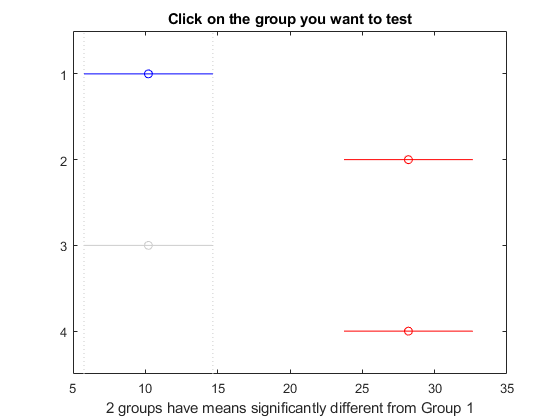

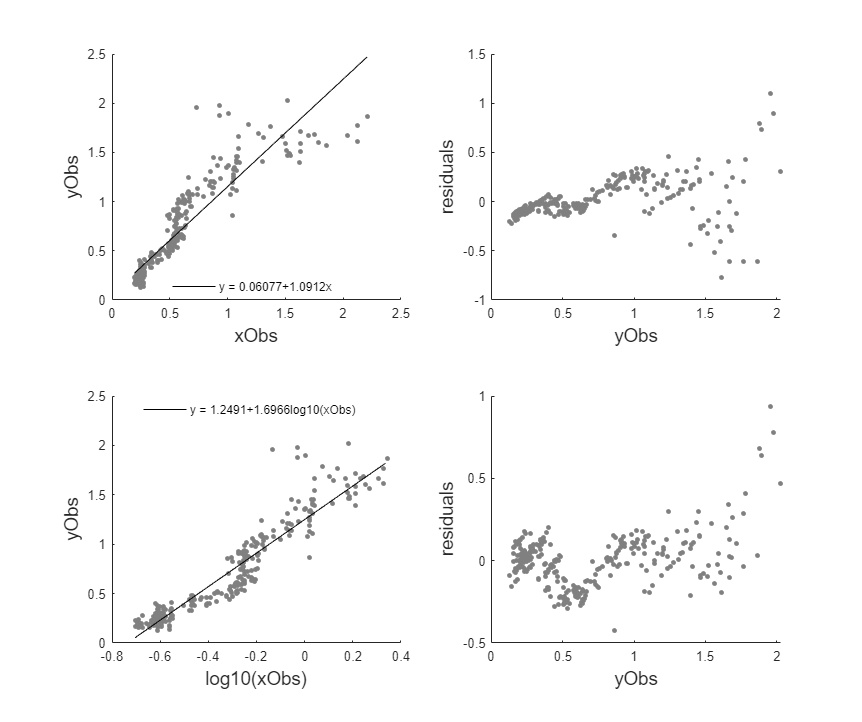

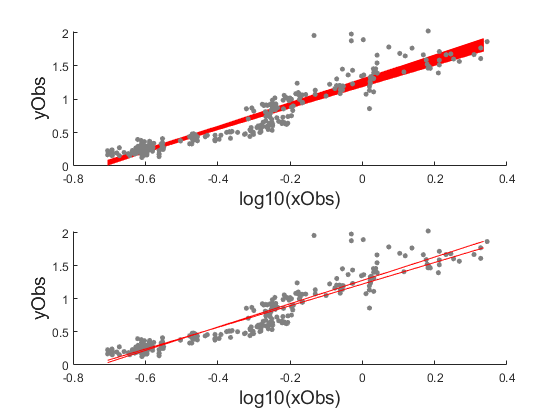

% p = p value: if less than the sig level (e.g. 0.05) then at least one group mean is different
% tbl = full anova table -  see MATLAB documentation (doc anova1)
% stats = full stats output - used for the multi comparison tests

multcompare(stats); % provides an interactive way of assessing which groups have means that are significantly different from other groups